#### Mason Mault June 2025

# Chebyshev Approximations and Interpolations

**Summary:**

The manual Discrete Chebyshev Transform and Barycentric interpolation are computed and compared to Chebfuns interpolation and truncation of the same degree. The manual FFT is built (recursively) to speed up the coefficient computation. Error and run times of the different methods are compared.

**Observations:**

The FFT speeds up the coefficient computation as n increases. Barycentric interpolation may be the most efficient method.

**To Do:** 

Reimplement the FFT non recursively. Find a better way of turning approximations into chebfuns than using chebfun.interp1(). Vectorize the for loops for performance. 

**Initialize grid and approximation degree information**

tic

% degree of approximation chosen so that n is a power of 2
power = 4;
n = 2^(power - 1);
       
% build grid points equally spaced by angle over [-1, 1]
theta = linspace(0, pi, n + 1);
xGrid = -cos(theta);

% fine grid for evaluating functions and their approximations
fine = 1e3;
thetaFine = linspace(0, pi, fine + 1);
xFine = -cos(thetaFine);

**Choose the function to approximate**

% sample the function at n + 1 points, then on the fine grid, then as a chebfun

% Power function, x.^p 
%
% p = 7;
% fSample = xGrid.^p + xGrid.^4 + 3*xGrid;
% fFine = xFine.^p + xFine.^4 + 3*xFine;
% fCheb = chebfun(@(x) x.^p + x.^4 + 3*x);
% fInterp = chebfun(@(x) x.^p + x.^4 + 3*x, n + 1);
% fTrunc = chebfun(@(x) x.^p + x.^4 + 3*x, 'trunc', n + 1);

% Runge function
% 
% fSample = 1 ./ (1 + 25*xGrid.^2);
% fFine = 1 ./ (1 + 25*xFine.^2);
% fCheb = chebfun(@(x) 1 / (1 + 25*x.^2));
% fInterp = chebfun(@(x) 1 / (1 + 25*x.^2), n + 1);
% fTrunc = chebfun(@(x) 1 / (1 + 25*x.^2), 'trunc', n + 1);

% sign function (manual and chebfun evaluate f(0) differently)
%
% fSample = sign(xGrid);
% fFine = sign(xFine);
% fCheb = chebfun(@(x) sign(x));
% fInterp = chebfun(@(x) sign(x), n + 1);
% fTrunc = chebfun(@(x) sign(x), 'trunc', n + 1);

% sawtooth wave (manual and chebfun interpolation are very different here,
% stems from the evaluation of f at 0)
%
% fSample = 2 * (xGrid - floor(xGrid + 1));
% fFine = 2 * (xFine - floor(xFine + 1));
% fCheb = chebfun(@(x) 2 * (x - floor(x + 1)));
% fInterp = chebfun(@(x) 2 * (x - floor(x + 1)), n + 1);
% fTrunc = chebfun(@(x) 2 * (x - floor(x + 1)), 'trunc', n + 1);

% abs value
%
% fSample = abs(xGrid);
% fFine = abs(xFine);
% fCheb = chebfun(@(x) abs(x));
% fInterp = chebfun(@(x) abs(x), n + 1);
% fTrunc = chebfun(@(x) abs(x), 'trunc',  n + 1);

% high frequency sine wave
%
% wn = 100;
% fSample = sin(wn * xGrid);
% fFine   = sin(wn * xFine);
% fCheb   = chebfun(@(x) sin(wn * x));
% fInterp = chebfun(@(x) sin(wn * x), n + 1);
% fTrunc  = chebfun(@(x) sin(wn * x), 'trunc', n + 1);

% hyperbolic tangent (with n = 4 recreates figure page 29 ATAP)

fSample = tanh(4*xGrid - 1);
fFine = tanh(4*xFine - 1);
fCheb = chebfun(@(x) tanh(4*x - 1));
fInterp = chebfun(@(x) tanh(4*x - 1), n + 1);
fTrunc = chebfun(@(x) tanh(4*x - 1), 'trunc', n + 1);

% exponential function
%
% fSample = exp(-xGrid.^2);
% fFine = exp(-xFine.^2);
% fCheb = chebfun(@(x) exp(-x.^2));
% fInterp = chebfun(@(x) exp(-x.^2), n + 1);
% fTrunc = chebfun(@(x) exp(-x.^2), 'trunc', n + 1);

% sum of functions
% wn = 100;
% fSample = sin(wn * xGrid) + exp(sin(xGrid) - xGrid.^2) + xGrid.^3;
% fFine   = sin(wn * xFine) + exp(sin(xFine) - xFine.^2) + xFine.^3;
% fCheb   = chebfun(@(x) sin(wn * x)) + chebfun(@(x) exp(sin(x) - x.^2)) + chebfun(@(x) x.^3);
% fInterp = chebfun(@(x) sin(wn * x), n + 1) + chebfun(@(x) exp(sin(x) - x.^2), n + 1) + chebfun(@(x) x.^3, n + 1);
% fTrunc  = chebfun(@(x) sin(wn * x), 'trunc', n + 1) + chebfun(@(x) exp(sin(x) - x.^2), 'trunc', n + 1) + chebfun(@(x) x.^3, 'trunc', n + 1); 

buildGridandTrueFunction_time = toc;

**Compute the discrete Chebyshev coefficients **$a_k$, given by

$a_k =\frac{2}{n}\sum_{j=1}^n {w_j \;y}_j \;T_k \left(x_j \right)$,    for each k = 1, ..., n - 1

with the factor 2/n replaced with 1/n for k = 0, n.

The weight $w_j$ taking value 1 everywehre, except for 1/2 at endpoints.

tic

% initialize coefficient vector
ak = zeros(n + 1, 1);

% initialize weight vectors
w = ones(n + 1, 1);
w(1) = 0.5;
w(end) = 0.5;

% assign aks
for k = 0:n
    sum1 = 0;
    for j = 0:n
        sum1 = sum1 + w(j+1)*fSample(j + 1)*cos(k * acos(xGrid(j + 1)));
    end
    if  k == 0 || k == n 
        ak(k + 1) = sum1/n;
    else
        ak(k + 1) = 2*sum1/n;
    end
end

buildChebCoeffs_time = toc;

**Build the discrete Chebyshev approximation of degree n on the fine grid**

tic

% initialize approximation
fApprox = zeros(size(xFine));
% fApprox_nPoint = zeros(size(xGrid));

% add the coefficients
for k = 0:n
    fApprox = fApprox + ak(k + 1).*cos(k * acos(xFine));
end

% for k = 0:n
%     fApprox_nPoint = fApprox_nPoint + ak(k + 1).*cos(k * acos(xGrid));
% end

buildChebApprox_time = toc;

**Recompute the discrete Chebyshev coefficients with the Fast Fourier Transform**

tic

% build even and odd parts of fSample without repeating the endpoints
fSample = fSample(:);
fExt = [fSample; flipud(fSample(2: end - 1))];

% compute FFT
F = real(manualFFT(fExt));

% extract Chebyshev coefficients
akFFT = F(1:n+1) / n;
akFFT(1) = akFFT(1)/2;
akFFT(end) = akFFT(end)/2;

akFFT = akFFT.* (-1).^(0:n)';

buildChebCoeffsFFT_time = toc;

**Rebuild the discrete Chebyshev approximation of degree n on the fine grid**

tic

% build discrete Chebyshev approximation with FFT coefficients
fApproxFFT = zeros(size(xFine));
for k = 0:n
    fApproxFFT = fApproxFFT + akFFT(k + 1).*cos(k * acos(xFine));
end

buildChebApproxFFT_time = toc;

**Build an interpolant with the Barycentric Interpolation formula through Chebyshev points**

% adapted/copied from Trefethen and Benrut's "Barycentric Lagrange Inteprolation"
% 2004 paper

tic

c = [1/2; ones(n - 1, 1); 1/2].*(-1).^((0:n)');

numer = zeros(size(xFine));
denom = numer;
exact = numer;

for j = 1:n+1
    xdiff = xFine - xGrid(j);
    temp = c(j)./xdiff;
    numer = numer + temp*fSample(j);
    denom = denom + temp;
    exact(xdiff == 0) = 1;
end

fBaryInterp = numer./denom;
jj = find(exact);
fBaryInterp(jj) = fFine(jj);

buildBaryInterp_time = toc;

**Plots**

Discrete Chebyshev Approximation with sampled function values

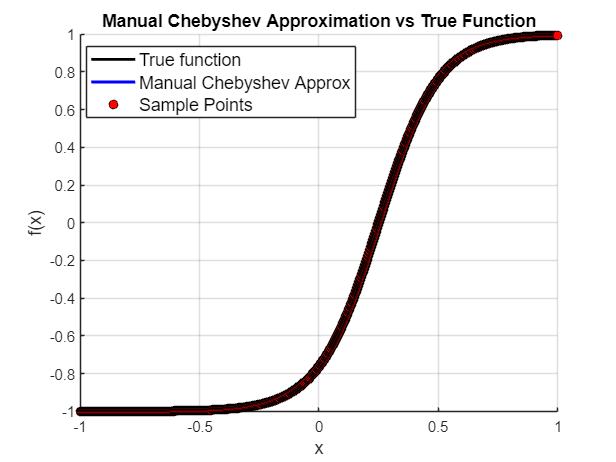

tic

figure
hold on

plot(xFine, fFine, 'k', 'LineWidth', 2, 'DisplayName', 'True function')
plot(xFine, fApprox, 'b', 'LineWidth', 2, 'DisplayName', 'Manual Chebyshev Approx')
plot(xGrid, fSample, 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'r', 'DisplayName', 'Sample Points')
title('Manual Chebyshev Approximation vs True Function', 'FontSize', 12, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

legend('Location', 'best', 'FontSize', 12, 'Box', 'on')

grid on

Plot Comparison of Manual Chebyshev Approximation and Chebfun Truncation and Interpolation

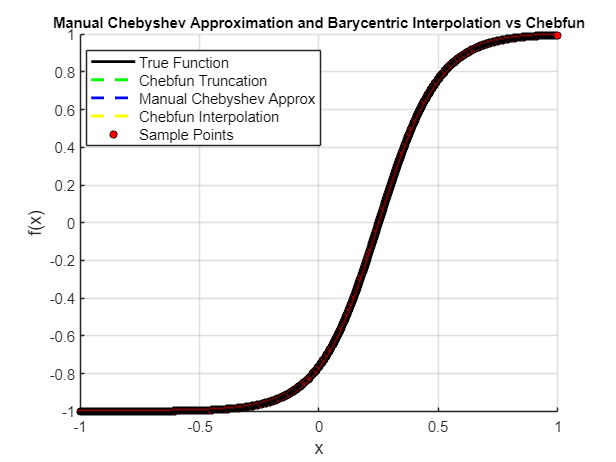

figure
hold on
plot(xFine, fFine, 'k-', 'LineWidth', 2, 'DisplayName', 'True Function')
plot(fTrunc, 'g--', 'LineWidth', 2, 'DisplayName', 'Chebfun Truncation')
plot(xFine, fApprox, 'b--', 'LineWidth', 2, 'DisplayName', 'Manual Chebyshev Approx')
plot(fInterp, 'y--', 'LineWidth', 2, 'DisplayName', 'Chebfun Interpolation')
plot(xGrid, fSample, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'DisplayName', 'Sample Points')

title('Manual Chebyshev Approximation and Barycentric Interpolation vs Chebfun', 'FontSize', 10, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)
legend('Location', 'best', 'FontSize', 10)
grid on

Plot comparison of manual Chebyshev approximation and manual Chebyshev interpolant

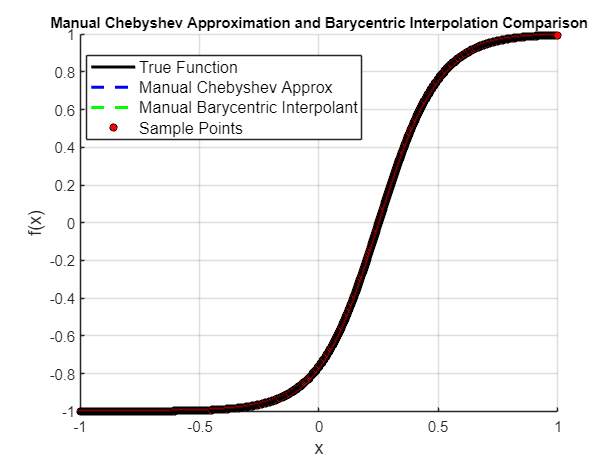

figure
hold on
plot(xFine, fFine, 'k-', 'LineWidth', 2, 'DisplayName', 'True Function')
plot(xFine, fApprox, 'b--', 'LineWidth', 2, 'DisplayName', 'Manual Chebyshev Approx')
plot(xFine, fBaryInterp, 'g--', 'LineWidth', 2, 'DisplayName', 'Manual Barycentric Interpolant')
plot(xGrid, fSample, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'DisplayName', 'Sample Points')

title('Manual Chebyshev Approximation and Barycentric Interpolation Comparison', 'FontSize', 10, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)
legend('Location', 'best', 'FontSize', 11)
grid on

Plot comparison of manual Chebyshev approximation with FFT and without

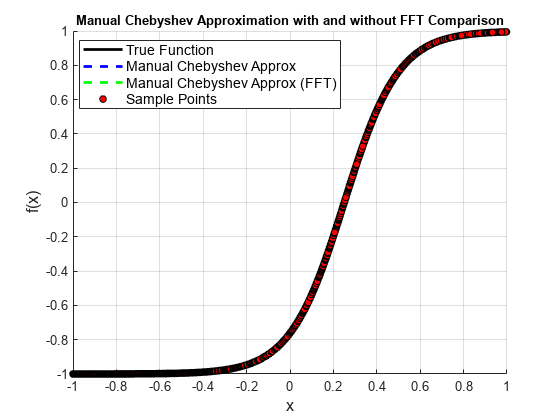

figure
hold on
plot(xFine, fFine, 'k-', 'LineWidth', 2, 'DisplayName', 'True Function')
plot(xFine, fApprox, 'b--', 'LineWidth', 2, 'DisplayName', 'Manual Chebyshev Approx')
plot(xFine, fApproxFFT, 'g--', 'LineWidth', 2, 'DisplayName', 'Manual Chebyshev Approx (FFT)')
plot(xGrid, fSample, 'ko', 'MarkerSize', 5, 'MarkerFaceColor', 'r', 'DisplayName', 'Sample Points')

title('Manual Chebyshev Approximation with and without FFT Comparison', 'FontSize', 10, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)
legend('Location', 'best', 'FontSize', 11)
grid on

**Error Analysis**

Differences from the true function 

The lines of code involving chebfun.interp1() are very slow if fine is large. Should consider alternative methods.

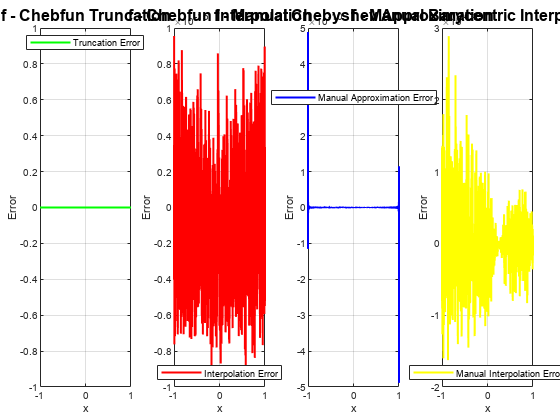

tic

% convert manual approximations and interpolation to chebfuns
fApprox_cheb = chebfun.interp1(xFine, fApprox);
fBaryInterp_cheb = chebfun.interp1(xFine, fBaryInterp);
fApproxFFT_cheb = chebfun.interp1(xFine, fApproxFFT);

convertManualtoChebfun_time = toc;

% build error subplots
figure('Name', 'Difference Between Exact and Approximate Chebfun Representations', 'NumberTitle', 'off');
tiledlayout(1, 4, 'Padding', 'compact', 'TileSpacing', 'compact');

% Subplot 1: True function - Chebfun truncation
nexttile
plot(fCheb - fTrunc, 'g', 'LineWidth', 1.5)
title('f - Chebfun Truncation', 'FontSize', 12, 'FontWeight', 'bold')
xlabel('x')
ylabel('Error')
grid on
legend('Truncation Error', 'Location', 'best')

% Subplot 2: True function - Chebfun interpolation
nexttile
plot(fCheb - fInterp, 'r', 'LineWidth', 1.5)
title('f - Chebfun Interpolation', 'FontSize', 12, 'FontWeight', 'bold')
xlabel('x')
ylabel('Error')
grid on
legend('Interpolation Error', 'Location', 'best')

% Subplot3: True function - Manual Chebyshev approximation 
nexttile
plot(fCheb - fApprox_cheb, 'b', 'LineWidth', 1.5)
title('f - Manual Chebyshev Approximation', 'FontSize', 12, 'FontWeight', 'bold')
xlabel('x')
ylabel('Error')
grid on
legend('Manual Approximation Error', 'Location', 'best')

% Subplot4: True funciton - Manual Chebyshev interpolation
nexttile
plot(fCheb - fBaryInterp_cheb, 'y', 'LineWidth', 1.5)
title('f - Manual Barycentric Interpolaation', 'FontSize', 12, 'FontWeight', 'bold')
xlabel('x')
ylabel('Error')
grid on
legend('Manual Interpolation Error', 'Location', 'best')

buildandShowPlot_time = toc;

**Compare infinity norms with the true function**

diffInterp = max(abs(fCheb - fInterp))

Out of memory.

Error in chebfun.ndct (line 76)
U = ChebP(K-1, ds) * besselCoeffs(K);

Error in chebtech/feval (line 48)
    y = chebfun.ndct(x, f.coeffs);

Error in chebtech/restrict (line 40)

diffManualApprox = max(abs(fCheb - fApprox_cheb))
diffTruncation = max(abs(fCheb - fTrunc))
diffBaryInterp = max(abs(fCheb - fBaryInterp_cheb))

**Compare manual Chebyshev approximation and Barycentric interpolation **

diffManuals = max(abs(fBaryInterp_cheb - fApprox_cheb))

**Compare manual Chebshev approximation with and without FFT**

diffFFTs = max(abs(fApprox_cheb - fApproxFFT_cheb))
max(abs(ak - akFFT))

**Compare Chebfun interpolation and manual Chebyshev approximation coefficients**

interpCoeffs = chebcoeffs(fInterp);
interpCoefDiff = max(abs(interpCoeffs - ak))

**Compare run times**

buildGridandTrueFunction_time

buildGridandTrueFunction_time = 0.0902

buildChebCoeffs_time

buildChebCoeffs_time = 2.2355

buildChebCoeffsFFT_time

buildChebCoeffsFFT_time = 0.0791

buildChebApprox_time

buildChebApprox_time = 0.1599

buildChebApproxFFT_time

buildChebApproxFFT_time = 0.1473

buildBaryInterp_time

buildBaryInterp_time = 0.0377

buildandShowPlot_time

buildandShowPlot_time = 0.6928

The following variable represents the run time needed to convert the manual approximation/interpolation to a chebfun. There may be more efficient ways to do this, as this value is large when fine (the size of the evaluation grid) becomes large (1e5).

convertManualtoChebfun_time

convertManualtoChebfun_time = 0.0577

**Fast Fourier Transform Function Definition**

function X = manualFFT(x)

    % enforce column vector
    x = x(:);
    N = length(x);
    if N == 1
        X = x;
    else
        % recursively call FFT of even and odd elements
        even = manualFFT(x(1:2:end));
        odd = manualFFT(x(2:2:end));

        % twiddle factors
        W = exp(-2i * pi * (0:(N/2 - 1))' / N);

        % build FFT
        X = [even + W.*odd; even - W.*odd];
    end
end